# Power of Deep Learning for joint Channel Estimation and Symbol Detection :

*Power of Deep Learning for Channel Estimation and Signal Detection in OFDM Systems : Hao Ye , Geoffrey Ye Li, Fellow, IEEE, and Biing-Hwang Juang, Fellow, IEEE*

The deep learning architecture presented in the paper is shown below :

                                                           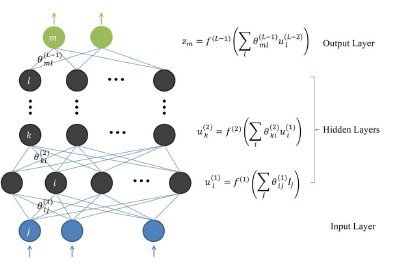

## Neural Network Structure :

The neural network is basically a FCNN, consisting of 5 layers whose size are shown below :

- First layer : 256 inputs -> ReLu layer

- Second layer : 500 neurons -> ReLu layer

- Third layer : 120 neurons -> Sigmoid layer

- Ouptut layer : 16 outputs -> Regression layer

layers = [sequenceInputLayer(256,'Name','InputLayer')
    fullyConnectedLayer(500,'Name','Layer1')
    reluLayer('Name','ReLu1')
    fullyConnectedLayer(120,'Name','Layer2')
    reluLayer('Name','ReLu2')
    fullyConnectedLayer(16,'Name','Layer3')
    sigmoidLayer('sigmoid')
    regressionLayer] ;

## Data Structure :

OFDM modulation is used for the system. The characteristics of the system are as follows :

- System frequency ($f_c$) : $2.66$ $GHz$

- Channel Model : Urban model with $24$ delay taps

- Pilots embedded in each frame

- Number of carriers ($N_c$) : $128$

- Number of pilot subcarriers ($N_p$) : 64 

The training data will be the real and complex part of the recieved signal concatenated together hence $128$ samples are received of which real and imaginary parts are concatenated and fed into the neural network. Thats why the input size is $256$.

nCarr = 128 ; % Number of Carriers
n_tx = 1; % Number of transmitting antenneas
cp_len = 16 ; % Cyclic Prefix length
p_flag = 1; % Provide pilots seperately
pilot_idx = (1:nCarr/2)'; % Index of pilot subcarriers for each OFDM symbol
SNR = 40; % SNR to calculate noise power

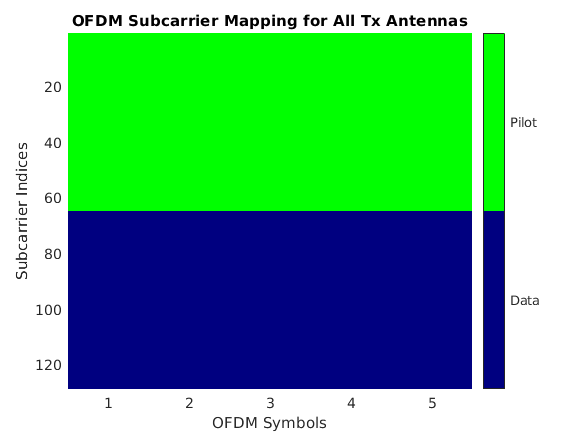

% Just for visulaization of our OFDM symbol and how the pilots are distributed this block can be run
nSym = 5 ;
[ofdm_mod,~] = OFDMConfig(nCarr,cp_len,nSym,n_tx,p_flag,pilot_idx);
showResourceMapping(ofdm_mod)

% Generating the training ,validate and test samples
ntrainSamples = 6000 ; % Number of traning samples
[trainData,trainLabels] = trainingData(nCarr,cp_len,n_tx,p_flag,ntrainSamples,pilot_idx,SNR);

%Generating the validation sets
nvalSamples = 5000 ; % Number of traning samples
[valData,valLabels] = trainingData(nCarr,cp_len,n_tx,p_flag,nvalSamples,pilot_idx,SNR);

%Generating test samples
ntestSamples = 2000;
[testData,testLabels] = trainingData(nCarr,cp_len,n_tx,p_flag,ntestSamples,pilot_idx,SNR);

## Traning the neural network :

We will be using the following options to train the neural network :

batchSize = 200;
valFrequency = round(size(trainData,2)/batchSize/5);
options = trainingOptions('adam', ...
    'ExecutionEnvironment','gpu',...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',10000, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MiniBatchSize',batchSize, ...
    'ValidationData',{valData, valLabels}, ...
    'ValidationFrequency',valFrequency, ...
    'ValidationPatience',5);

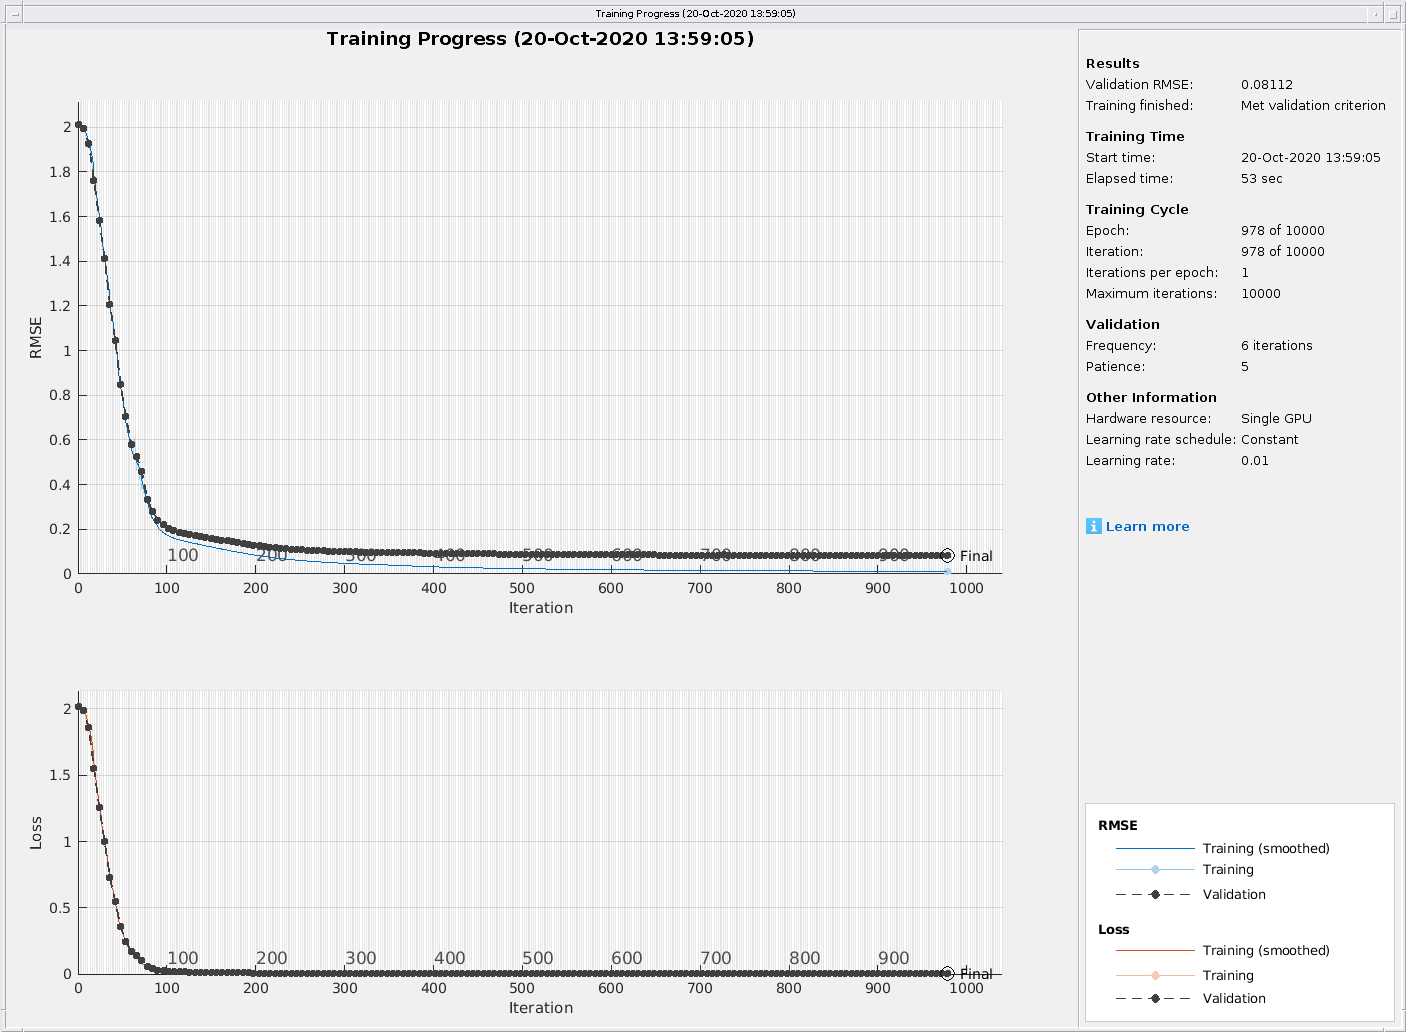

powerDL =   SeriesNetwork with properties:

    Layers: [8×1 nnet.cnn.layer.Layer]


trainingInfo = struct with fields:
      TrainingLoss: [1×978 double]
      TrainingRMSE: [1×978 double]
    ValidationLoss: [1×978 double]
    ValidationRMSE: [1×978 double]
     BaseLearnRate: [1×978 double]


[powerDL,trainingInfo] = trainNetwork(trainData, ...
                                          trainLabels,layers,options)

save ./powerDL_40dB.mat powerDL 

% Testing the data for the model
out = zeros(size(testLabels));
num = ones(1,ntestSamples);
for i = 1:size(testLabels,2)
    out(:,i) = predict(powerDL,testData(:,i));
    num(:,i) = biterr(testLabels(:,i),round(out(:,i)))/16;
end

x=mean(num)

x = 4.0625e-04